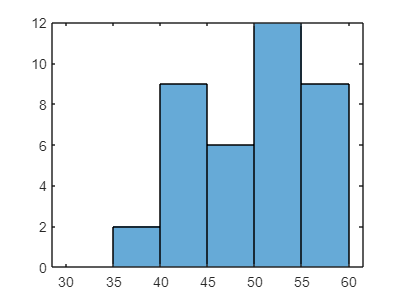

clear;
clc;
load("HeartDisease.mat");
%heart attack
count_male = 0;
count_female = 0;
typical_angina_count = 0;
atypical_angina_count = 0 ;
non_anginal_pain_count = 0;
asymptomatic_count = 0;
high_fbs_count = 0;
low_fbs_count =0;
normal_ecg_count =0;
STT_ecg_count =0;
left_ventricular_hypertrophy_count =0;
exercise_induced_agnima_count =0;
non_exercise_induced_agnima_count =0;
upsloping_count =0;
flat_count =0;
down_sloping_count =0;
zero_vessel_count = 0;
one_vessel_count =0;
two_vessel_count =0;
three_vessel_count =0;
normal_thalium_count =0;
fixed_defect_thalium_count =0;
reversable_defect_thalium_count =0;

%healthy
count_male_h = 0;
count_female_h = 0;
typical_angina_count_h = 0;
atypical_angina_count_h = 0 ;
non_anginal_pain_count_h = 0;
asymptomatic_count_h = 0;
high_fbs_count_h = 0;
low_fbs_count_h =0;
normal_ecg_count_h =0;
STT_ecg_count_h =0;
left_ventricular_hypertrophy_count_h =0;
exercise_induced_agnima_count_h =0;
non_exercise_induced_agnima_count_h =0;
upsloping_count_h =0;
flat_count_h =0;
down_sloping_count_h =0;
zero_vessel_count_h = 0;
one_vessel_count_h =0;
two_vessel_count_h =0;
three_vessel_count_h =0;
normal_thalium_count_h =0;
fixed_defect_thalium_count_h =0;
reversable_defect_thalium_count_h =0;
for t=1:size(T)
      if ((T(t,14) >= 1 ))
         heart_attack(t,:)= T(t,:);
      elseif((T(t,14) == 0 ))
          healthy(t,:) = T(t,:);
      end

end

heart_attack=removezero(heart_attack);
healthy = removezero(healthy);

chest_pain_type =fourvariable(heart_attack,typical_angina_count,atypical_angina_count,non_anginal_pain_count,asymptomatic_count,3,1,2,3,4);

fbs = twovaraible(heart_attack,high_fbs_count,low_fbs_count,6,1,0);

ecg= threevaraible(heart_attack,normal_ecg_count,STT_ecg_count,left_ventricular_hypertrophy_count,7,0,1,2);


exang = twovaraible(heart_attack,exercise_induced_agnima_count,non_exercise_induced_agnima_count,9,1,0);

slope =  threevaraible(heart_attack,upsloping_count,flat_count,down_sloping_count,11,1,2,3);

ca=fourvariable(heart_attack,zero_vessel_count,one_vessel_count,two_vessel_count,three_vessel_count,12,0,1,2,3);

thal= threevaraible(heart_attack,normal_thalium_count,fixed_defect_thalium_count,reversable_defect_thalium_count,13,3,6,7);


gender = twovaraible(heart_attack,count_male,count_female,2,1,0);

chest_paint_type_h=fourvariable(healthy,typical_angina_count_h,atypical_angina_count_h,non_anginal_pain_count_h,asymptomatic_count_h,3,1,2,3,4);

fbs_h = twovaraible(healthy,high_fbs_count_h,low_fbs_count_h,6,1,0);

ecg_h=threevaraible(healthy,normal_ecg_count_h,STT_ecg_count_h,left_ventricular_hypertrophy_count_h,7,0,1,2);

exang_h = twovaraible(healthy,exercise_induced_agnima_count_h,non_exercise_induced_agnima_count_h,9,1,0);

slope_h =  threevaraible(healthy,upsloping_count_h,flat_count_h,down_sloping_count_h,11,1,2,3);

ca_h=fourvariable(healthy,zero_vessel_count_h,one_vessel_count_h, two_vessel_count_h,three_vessel_count_h,12,0,1,2,3);

thal_h=threevaraible(healthy,normal_thalium_count_h,fixed_defect_thalium_count_h,reversable_defect_thalium_count_h,13,3,6,7);

gender_h = twovaraible(healthy,count_male_h,count_female_h,2,1,0);

y =(30:5:60);
figure(1) 
histogram(healthy(:,1),y)

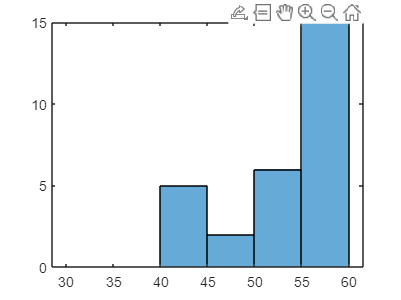

figure(2) 
histogram(heart_attack(:,1),y)


[avg,sdv] = calculationstdev_mean(heart_attack(:,1))

avg = 56.5641

sdv = 7.6254

[avg_h,sdv_h] = calculationstdev_mean(healthy(:,1))

avg_h = 52.9583

sdv_h = 8.6220

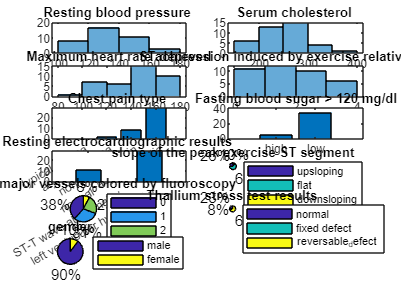


plotting(heart_attack,chest_pain_type,fbs,ecg,exang,slope,ca,thal,gender,3);

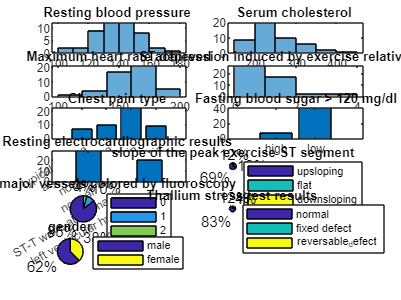


plotting(healthy,chest_paint_type_h,fbs_h,ecg_h,exang_h,slope_h,ca_h,thal_h,gender_h,4);


prob_female = count_female/88 *100;
prob_male = count_male /88 *100;



function arr = removezero(x)
    indices = find(x(:,1) == 0);
    x(indices,:) = [];
    arr=x;
end

function z = fourvariable(x,a,b,c,d,col,h,j,k,l)
    for t=1:size(x)
        switch(x(t,col))
            case h
                a = a +1 ;
            case j
                b = b +1;
            case k
                c = c+1;
            case l
                d = d +1;
        end
    end
    z = [a,b,c,d];
end
function z = threevaraible(x,a,b,c,col,j,k,l)
    for t=1:size(x)
        switch(x(t,col))
            case j
                a = a +1 ;
            case k
                b = b +1;
            case l
                c = c+1;
        end
    end
    z = [a,b,c];
end

function z = twovaraible(x,a,b,col,h,k)
    for t=1:size(x)
        switch(x(t,col))
            case h
                a = a +1 ;
            case k
                b = b +1;
        end
    end
    z = [a,b];
end

function plotting(x,a,b,c,d,e,f,g,h,n)
    figure(n)
    subplot(6,2,1)
    histogram(x(:,4))
    title("Resting blood pressure ")
    subplot(6,2,2)
    histogram(x(:,5))
    title("Serum cholesterol ")
    subplot(6,2,3)
    histogram(x(:,8))
    title("Maximum heart rate achieved")
    subplot(6,2,4)
    histogram(x(:,10))
    title("ST depression induced by exercise relative to rest")

    subplot(6,2,5)
    bar(a)
    title("Chest pain type ")
    xticklabels({'typical angina','atypical angina','non-anginal pain','asymptomatic'})


    subplot(6,2,6)
    bar(b)
    title("Fasting blood sugar > 120 mg/dl")
    xticklabels({'high','low'})


    subplot(6,2,7)
    bar(c)
title("Resting electrocardiographic results ")
xticklabels({'normal','ST-T wave abnormality ','left ventricular hypertrophy'})


subplot(6,2,8)
bar(d)
title("Exercise-induced angina ")
xticklabels({'yes','no '})


subplot(6,2,8)
pie(e)
legend('upsloping','flat','downsloping','Location','eastoutside')
title("slope of the peak exercise ST segment")


subplot(6,2,9)
pie(f)
legend('0','1','2','3','Location','eastoutside')
title("Number of major vessels colored by fluoroscopy")


subplot(6,2,10)
pie(g)
legend('normal','fixed defect','reversable_defect','Location','eastoutside')
title("Thallium stress test results")

    subplot(6,2,11)
    pie(h)
    legend('male','female','Location','eastoutside')
    title("gender")
end
function [m,n] = calculationstdev_mean(x)
    m = mean(x);
    n = std(x);
end




